# Embedded AI: Hands-on Workshop

## Environment Setup

1.Create a working folder in the MATLAB working directory. The default will be "C:\Users\<your username>\Documents\MATLAB\Hands-on workshop".

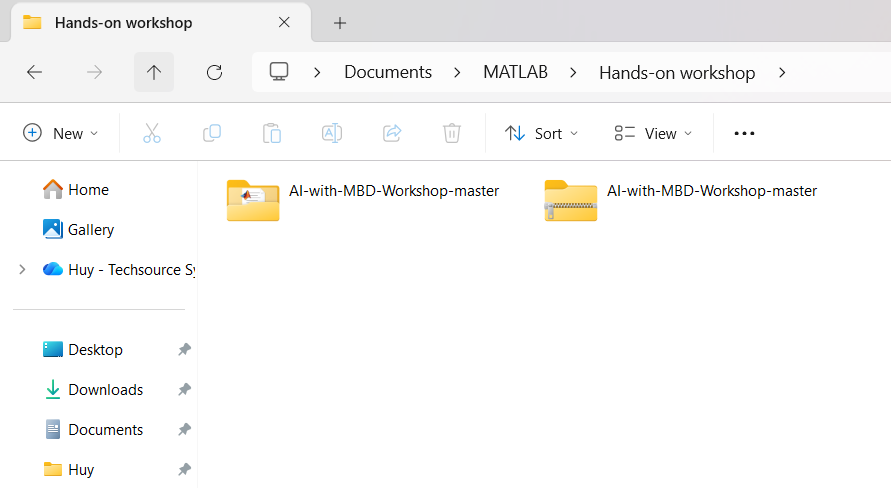

2.Copy a zip file download from Github to folder and extract.

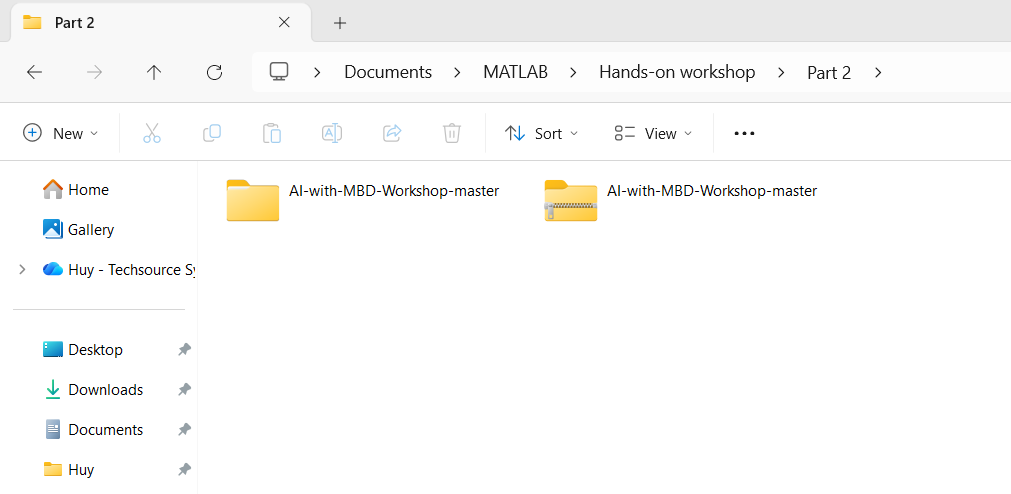

3.Add Hands-on workshop folder to MATLAB Path. Select Add Folder with Subfolders then navigate to the "Hands-on workshop" folder then click "Apply".

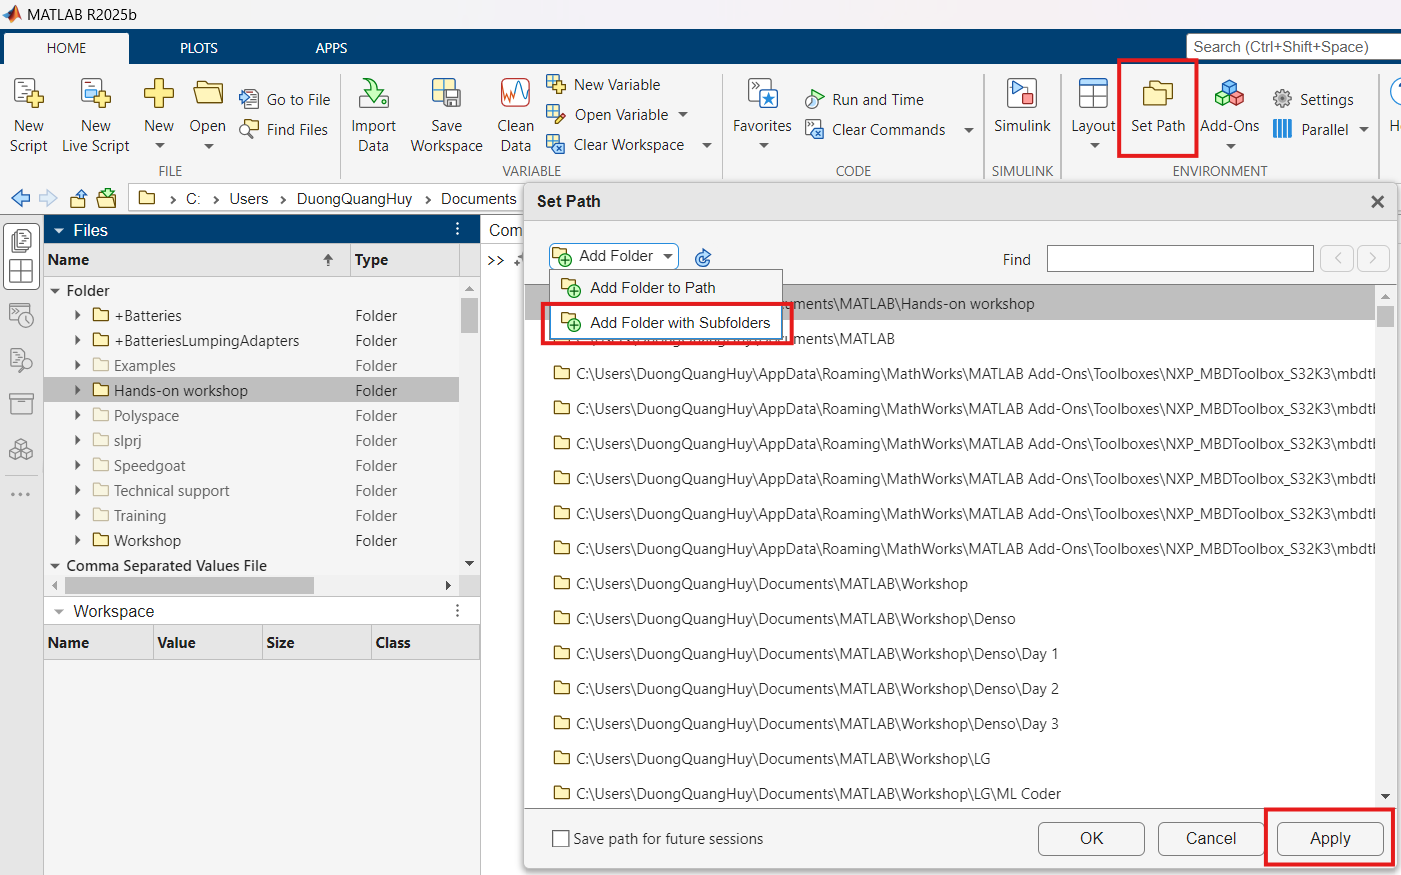

## Part 1: Battery State-of-Charge (SOC) Estimation using a Feed-Forward Network

Go in the “AI-with-MBD-Workshop-master” folder. Double click to open the project.

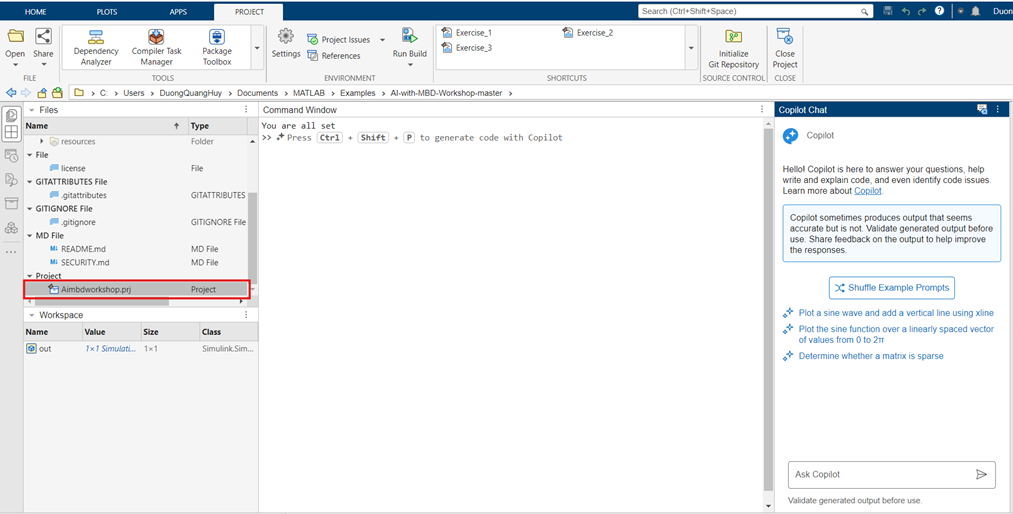

### 1.Data Preparation

The training data contains a single sequence of experimental data collected while the battery powered an electric vehicle during a driving four driving cycles at different temperatures (-10ºC, 0ºC, 10ºC and 25ºC). The test data contains four sequences of experimental data collected during driving cycles at the same temperatures. This example uses the preprocessed data set `LG_HG2_Prepared_Dataset_McMasterUniversity_Jan_2020` from [1]. You can download this data set manually from [https://data.mendeley.com/datasets/cp3473x7xv/3](https://data.mendeley.com/datasets/cp3473x7xv/3). 

We have data stored in three different folders: Test, Train and Validation.

All data is already stored in ".mat" files, the input variables in a matrix X and the response variables in Y.

clear
if isempty(matlab.project.rootProject)
    error("No project loaded. Please load Aimbdworkshop.prj to proceed.")
else
    dataFolder = helper.getDataFolder();
end 

### 2.Load Train & Test Data

"numFeatures" denotes the number of inputs features used. We can choose from five features (voltage, current, temperature, V_avg, I_avg), where the last two (V_avg, I_avg) are the averaged values for voltage and current.

trainingFile = fullfile(dataFolder,"Train", ...
    "TRAIN_LGHG2@n10degC_to_25degC_Norm_5Inputs.mat");
[X,Y] = helper.loadData(trainingFile);


validationFile = fullfile(dataFolder,"Validation", ...
    "01_TEST_LGHG2@n10degC_Norm_(05_Inputs).mat");
[valX,valY] = helper.loadData(validationFile);

### 3.Build an AI Model - Define Neural Network Architecture

There are many possible choices for defining the network architecture. We have three base predictors, voltage, current and temperature. We can also use moving averages of voltage (V_avg) and currrent (I_avg) in order to provide the network with information about past values. This is useful for improving the accuracy of feedforward networks, but not equally necessary with other networks like the recurrent networks such as LSTM (long short-term memory), or GRU (gated recurrent unit).

Let's use the following MLP (multi-layer perceptron) model. It is probably one of the simplest architectures you could choose.  You can define the network programmatically or use a graphical interface provided by the **Deep Network Designer** app. For this exercise, we will define a partial network programmatically and then complete the architechture using the **Deep Network Designer** app. 

% Define the first two layers programmatically 
layers = [
    featureInputLayer(5,"Name","featureinput")
    fullyConnectedLayer(128,"Name","fc")];

In the Deep Network Designer App we define the network architecture via dragging and dropping the layers from the layer library to the left. You can also search for layers in the library by name. Here is how we build the rest of the network:

**TODO: Add the two highlighted layers to the network with their respective property values shown in the diagram below.**

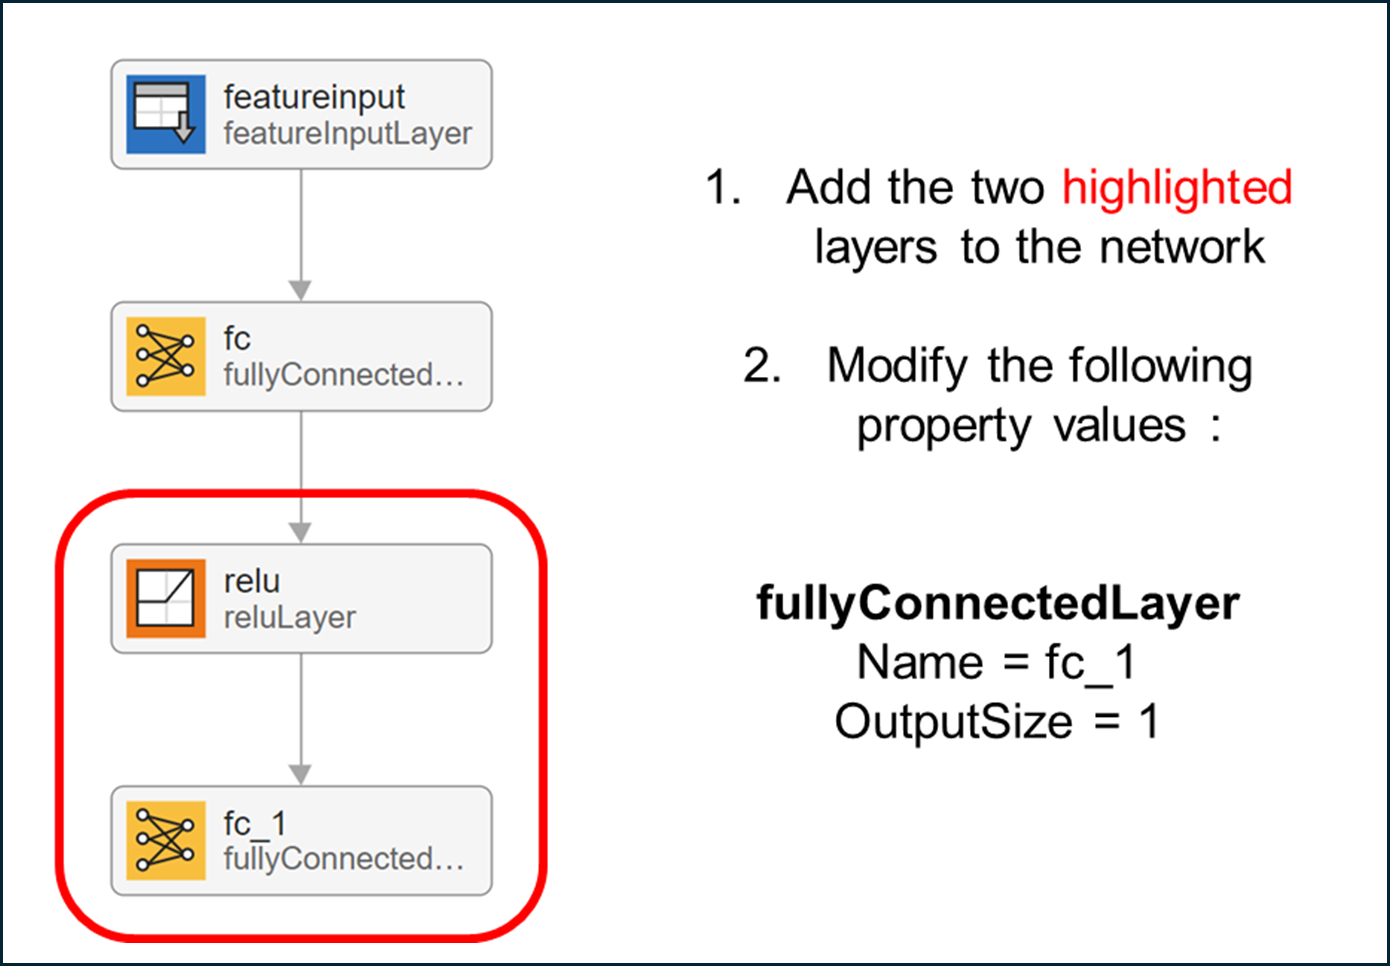

When you are done, you can click the Analyze button to  understand the architecture of a network, check that you have defined the architecture correctly, and detect problems before training.

deepNetworkDesigner(layers)

### 4.Export the network architecture to the MATLAB workspace

Now, we can go ahead an export the network to the MATLAB workspace. We click the green Export checkmark and select "Export to workspace".

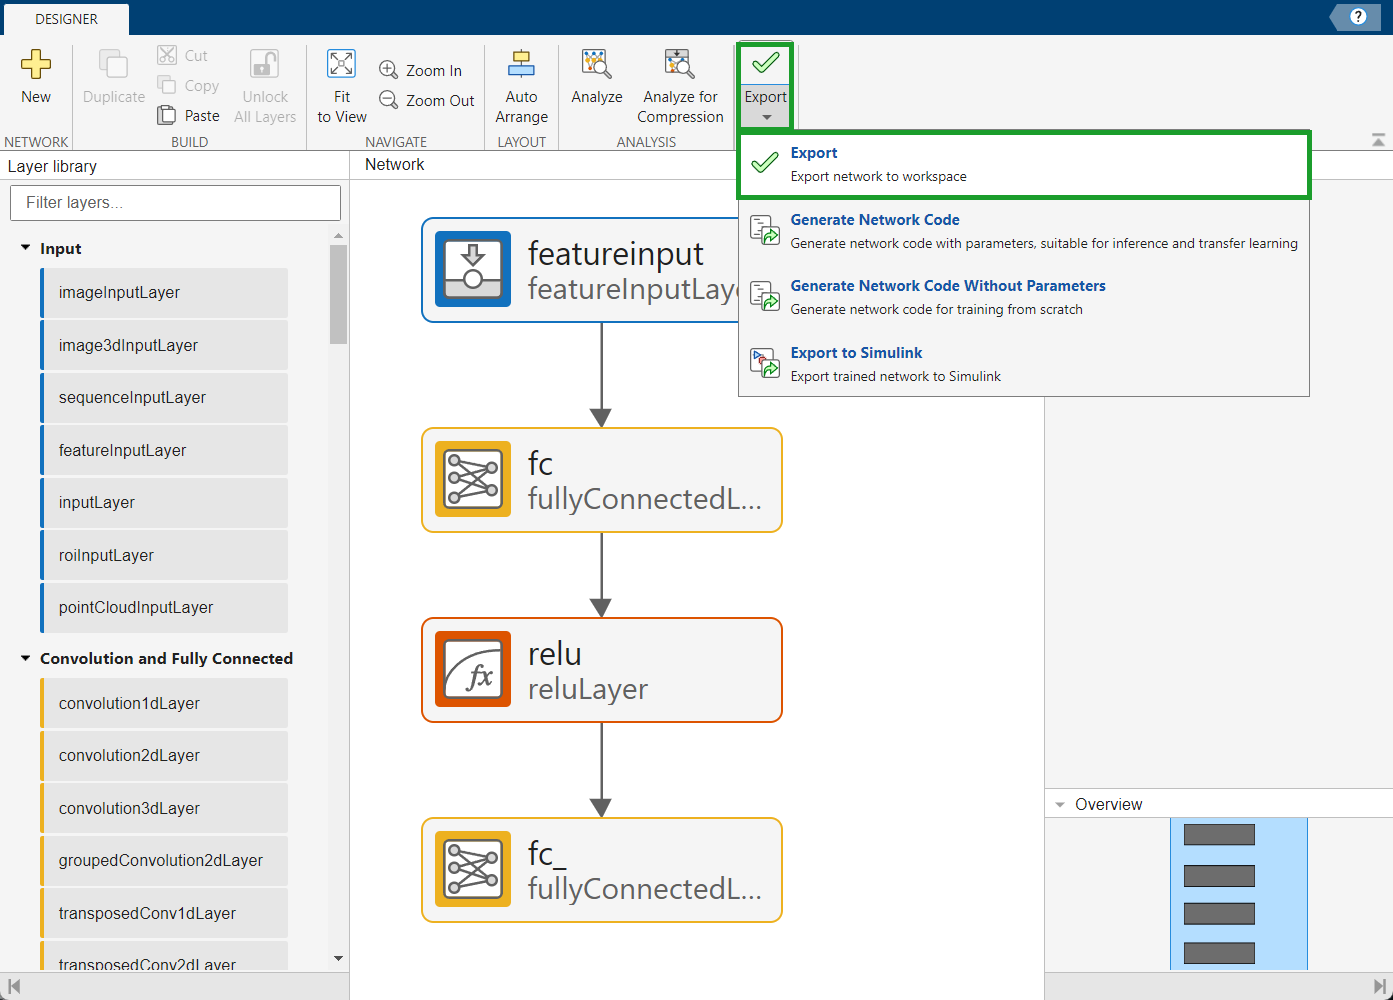

Specify the name of the network as net_1.

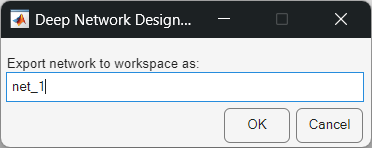

A dialog appears stating that the export to the variable net_`1` was successful.

If our network was already trained, we could directly export from here to Simulink as well.

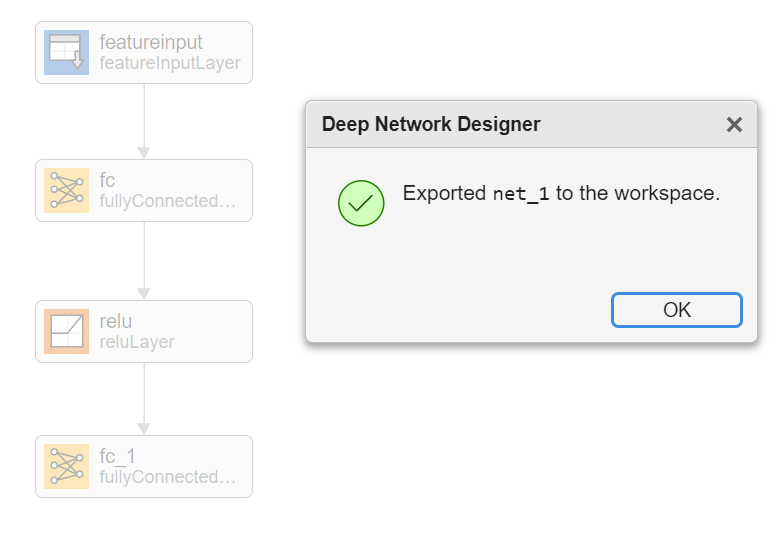

### 5.Set Training Options and train the network

There are many settings that control the training algorithm. Among the most important are

- **Solver**: Which solver to use, e.g. SGDM or ADAM

- **InitialLearnRate**: determines the step size of the algorithm. 

- **MaxEpochs**: controls how many passes through the entire data set are made

**TODO:**

Try out different values for the control elements and retrain via executing this section only. Some values we tried that work relatively well:

*Note* If you want to train by your self please select "true" / If you want to load pretrained select "false"*

1) Set the **Solver** to "adam"

2) Set the **InitialLearnRate** to 0.001

3) Set the **MiniBatchSize** to 1000

4) Set **MaxExpochs** to 3

Also, we want to plot our training progress including the validation data:

shouldTrainModel = true;

if shouldTrainModel
    solverName = ("sgdm");
    initialLearnRate = 0.01;
    miniBatchSize =4800;
    maxEpochs = 5;
    
    options = trainingOptions(solverName, ...
      'InitialLearnRate',initialLearnRate, ...
      'MiniBatchSize', miniBatchSize,...
      'MaxEpochs',maxEpochs, ...
      'Plots','training-progress',...
      'ValidationData',{valX, valY});
    
    trainedNetwork = trainnet(X,Y,net_1,"mse",options);
else 
    load("trainedNetwork.mat");
end

### 6.Evaluate the network on a held-out test data set

A key step in order to evaluate the network performance and for comparison of different networks is running inference on a separate test data set:

testFile = fullfile(dataFolder,"Test","04_TEST_LGHG2@25degC_Norm_(05_Inputs).mat");
S = load(testFile);
prediction = trainedNetwork.predict(S.X');
figure
plot(prediction)
hold on
plot(S.Y)
legend(["network prediction","true SoC"])

### 7.Save the AI Model as a File

You can save the workspace variable as a file in the current directory.

save(fullfile(helper.getCurrPartFolder("P1"), "myTrainedNetwork.mat"), "trainedNetwork");

### **8.Generate the Inputs for Simulink**

In Simulink, there are several ways how you can import data: "From Workspace" block, "Inport" block, "From File" block and others. We are going to use "From Workspace" blocks. We need to generate the inputs for Simulink in the correct format and we can use the left-out test data set.

steps = size(S.X,2);
t = (0:(steps-1))';

X_in = timeseries(single(S.X'), t);
true_SOC = timeseries(single(S.Y'), t);

### 9.Launch Simulink:

simulink

Create a new blank model:

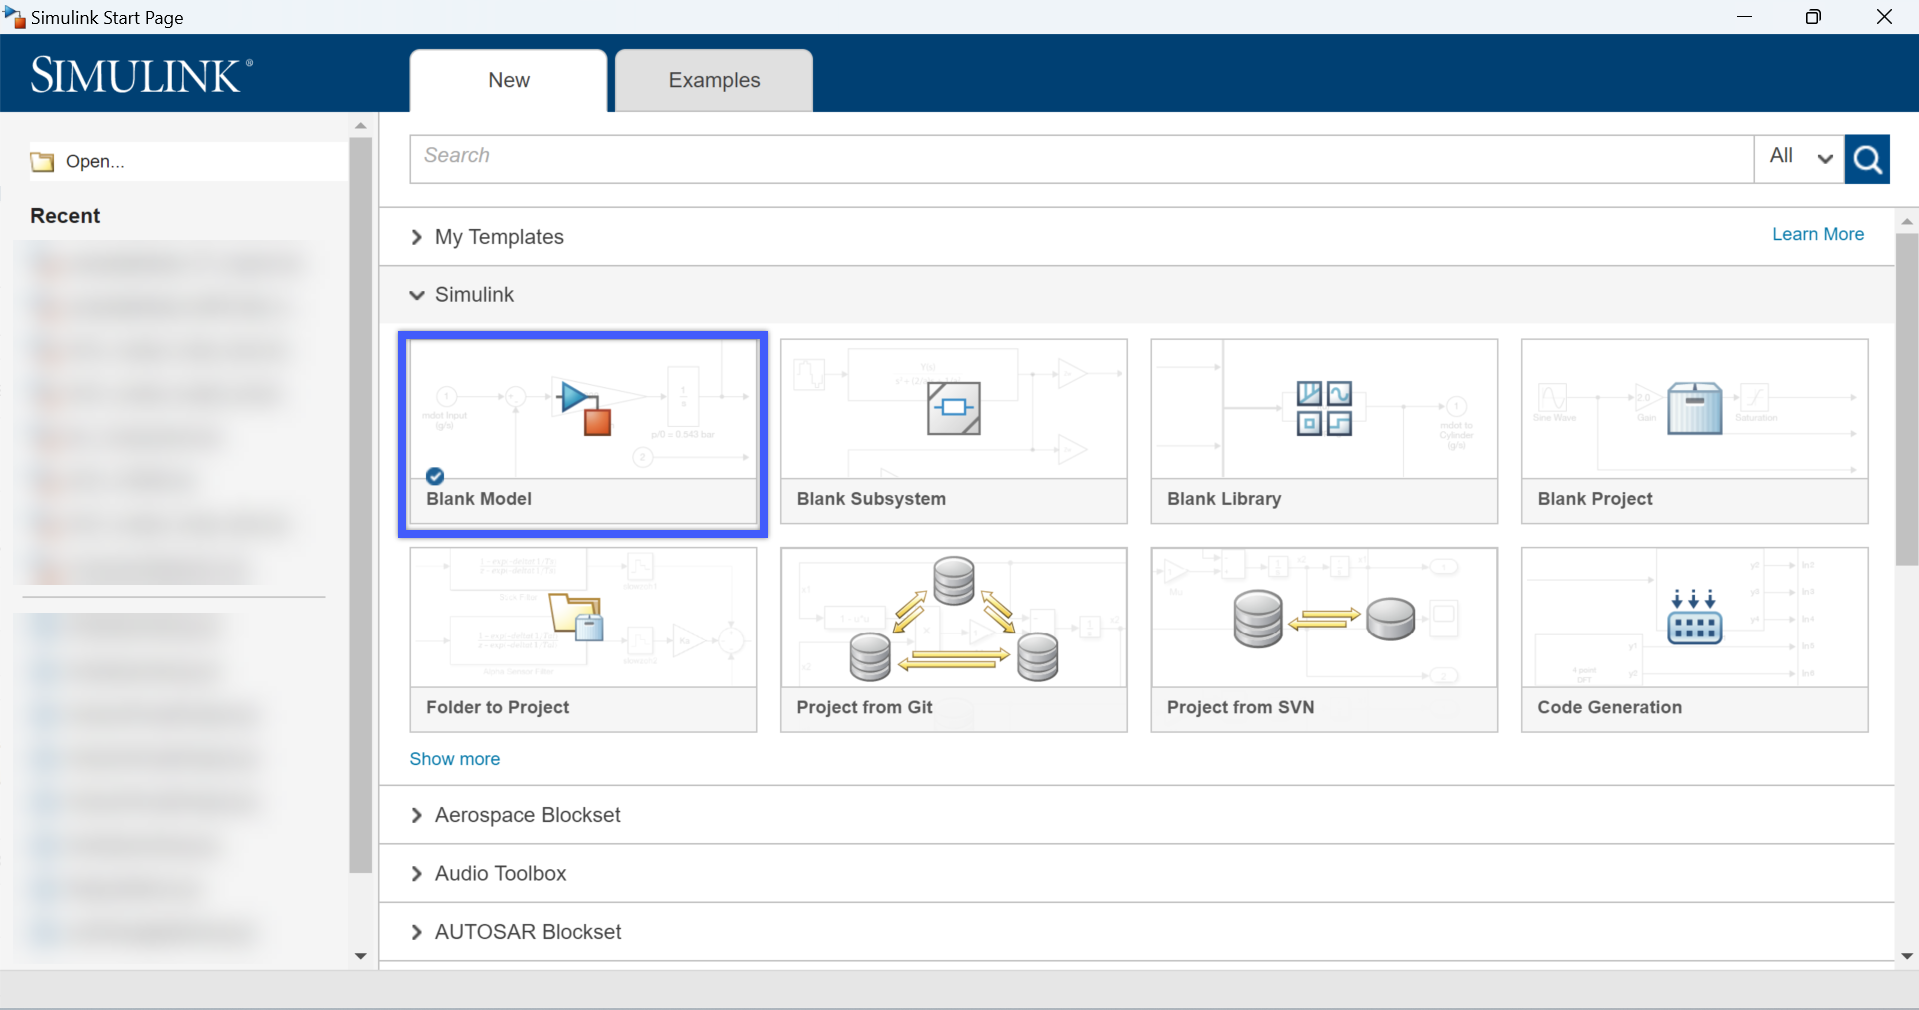

Add a "Predict" block using search in **Library Browser**, or by double-clicking on the Simulink canvas to type "Predict" in quick insert.

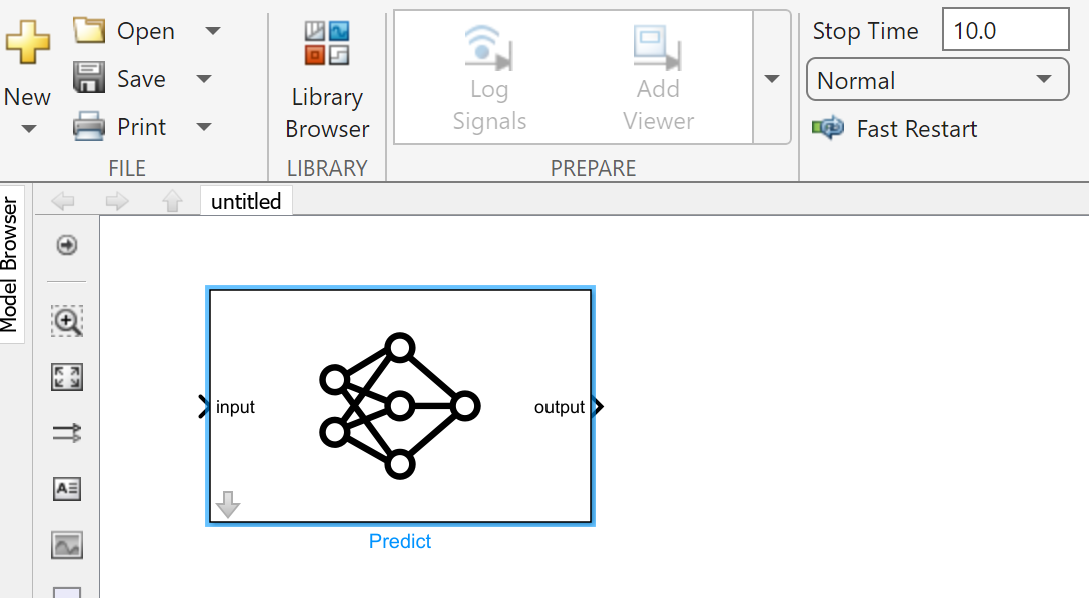

### 10.Configure Network to Use for Predict Block

Double click on the **Predict Block** to open the **Block Parameters** menu. Specify the path to the myTrainedNet.mat in the current directory as the File path. Specify the **Input data format** as "CB" - this means the input data is formatted as *c*-by-*n* array, where *c* is the number of features, and *n* is the number of observations. Save the model.

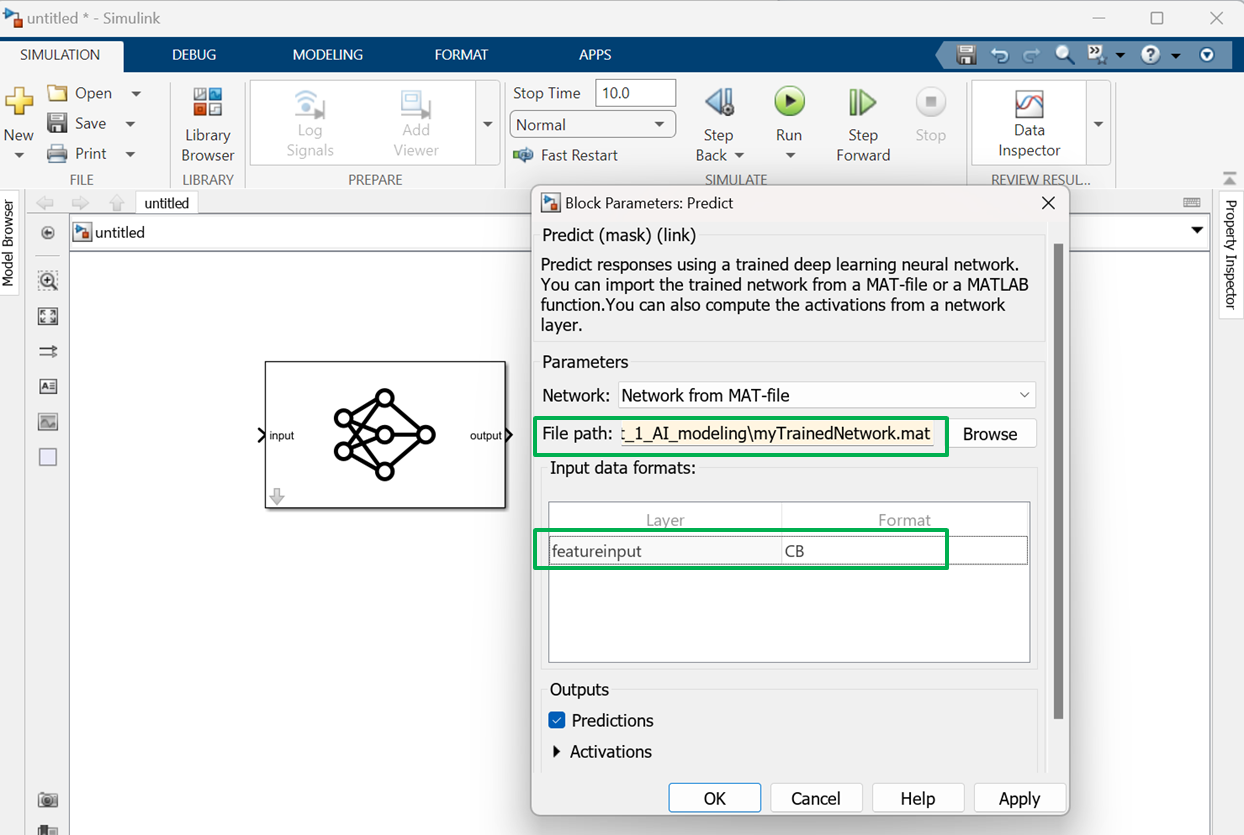

### 11.Configure Model Parameters for Simulations

Open the **Configuration Parameters** dialog (or Ctrl+E) and set **Stop time **to the workspace variable named "steps" (which is the total number of simulation steps; this variable will be generated in a later section), and set the solver to "Fixed-step" and "Discrete" with a fundamental step size of 1:

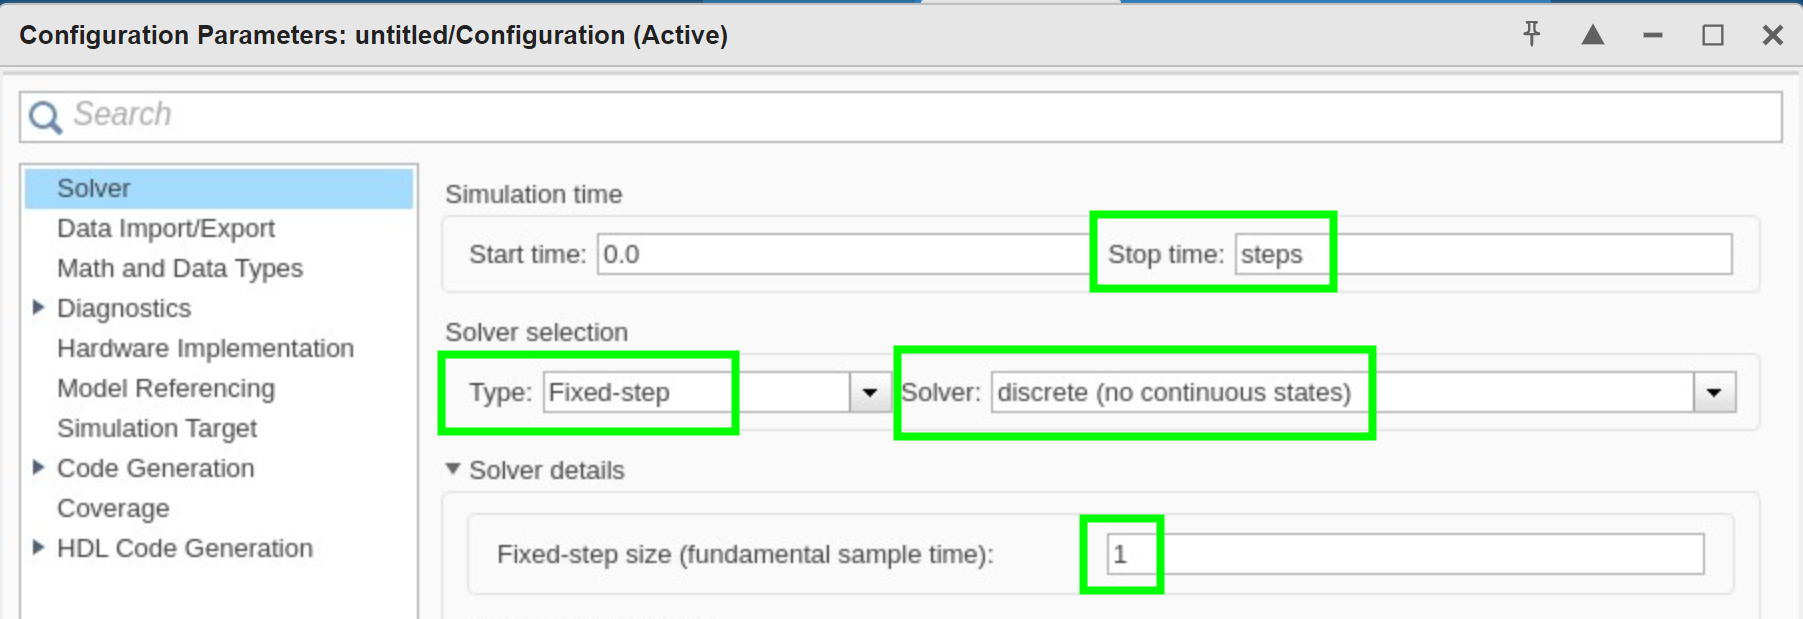

### **12.Connect the Model**

Save the model as myE`xampleModel.slx`. Then add two "From Workspace" blocks with "X_in" and "true_SOC" for the data variables, respectively. Connect the "X_in" input to the "Predict" block. Connect the outputs with a "Scope" block in the following way:

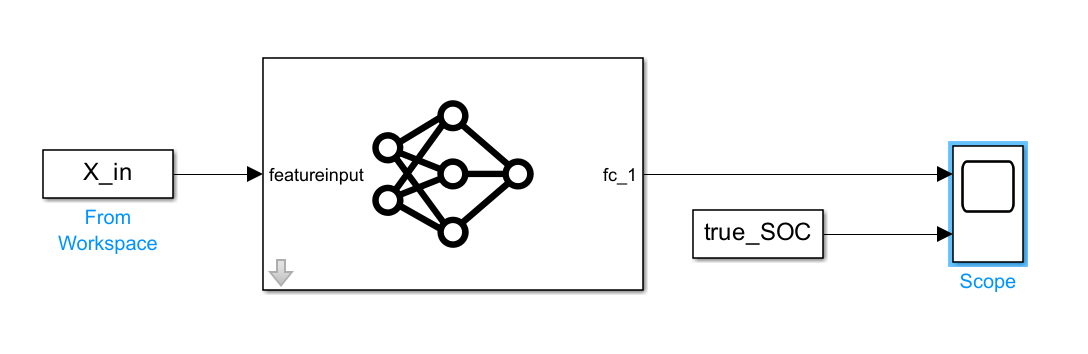

### 13.Run the Simulink Model

Now we can simulate the model by clicking the "Run" button and double-click on the "Scope" block to inspect simulation results:

(You may check `exampleModel_MATLAB_model.slx` if you run into any issues)

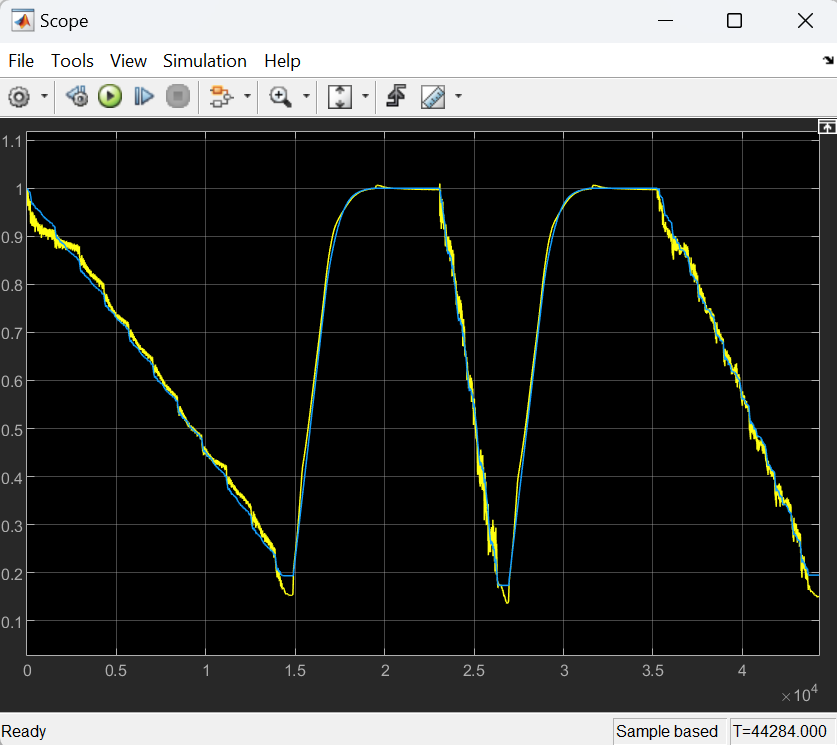

## Part 2: Integrate AI models into Simulink for simulation and code generation.

### 1.Unzip the TensorFlow™ Model

The TensorFlow model is available in a zipped folder. Unzip the folder to access it in MATLAB. 

clear
proj = currentProject;
unzip(helper.getPyModelFolder,helper.getCurrPartFolder("P2"))

### 2.Import Network using Deep Network Designer

Launch the Deep Network Designer:

deepNetworkDesigner

Click on "Import" in the "From TensorFlow" option from the Start Page. If you've not installed **Deep Learning Toolbox Converter for TensorFlow Models**, you can first click the "Install" button and then click on "Import" after the installation is complete.

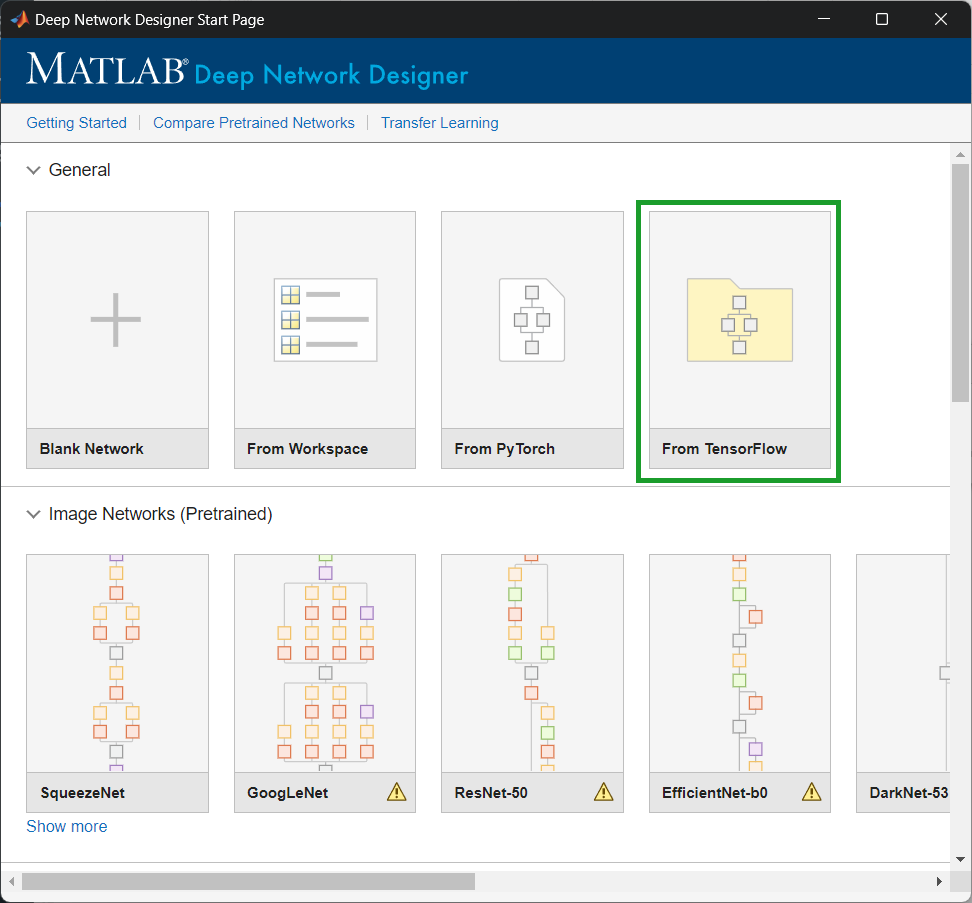

Select the **folder** that contains the TensorFlow model. Click "Import".

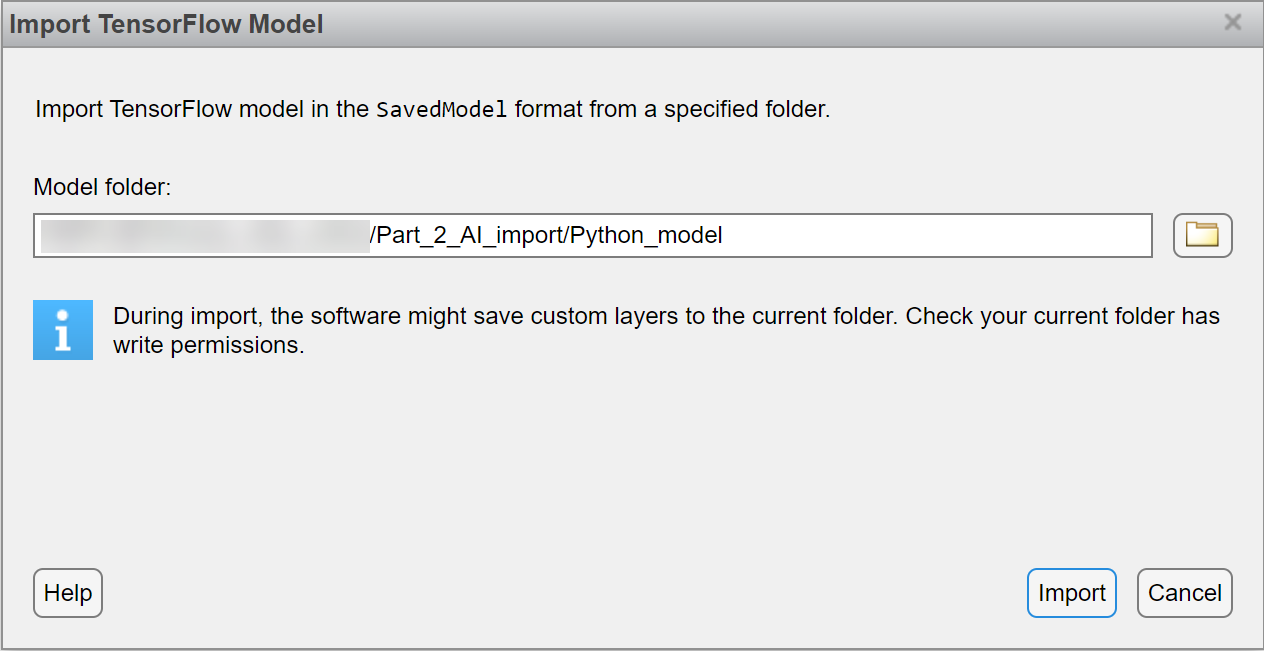

Import Progress is showned in the menu.

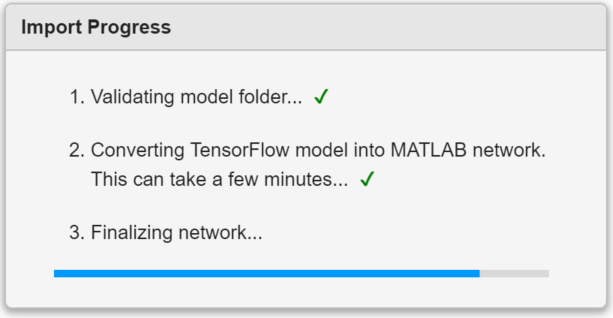

### 3.Review Network Design

After import is complete, click on the "Designer" tab to inspect the network architecture and confirm properties of individual layers.

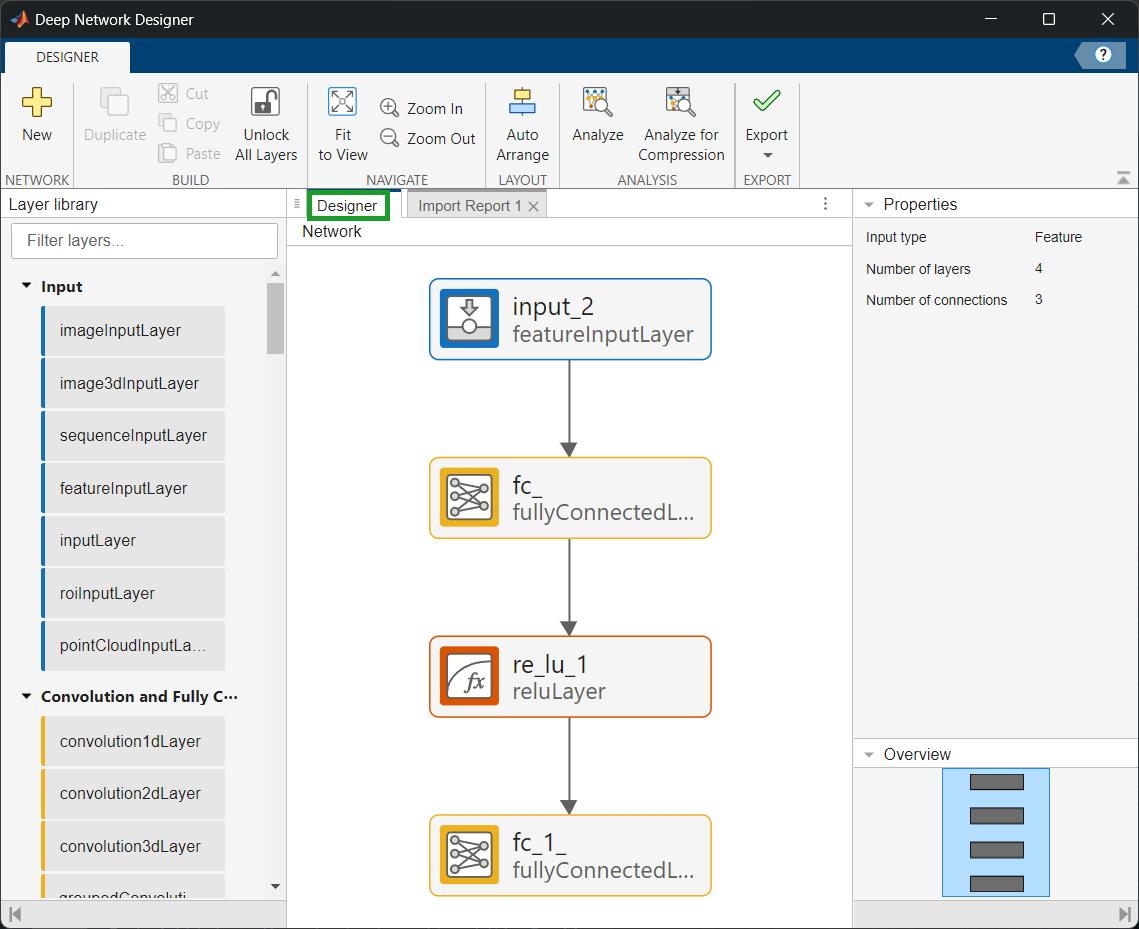

### 4.Export AI Model

Export the AI model to Simulink from the toolstrip.

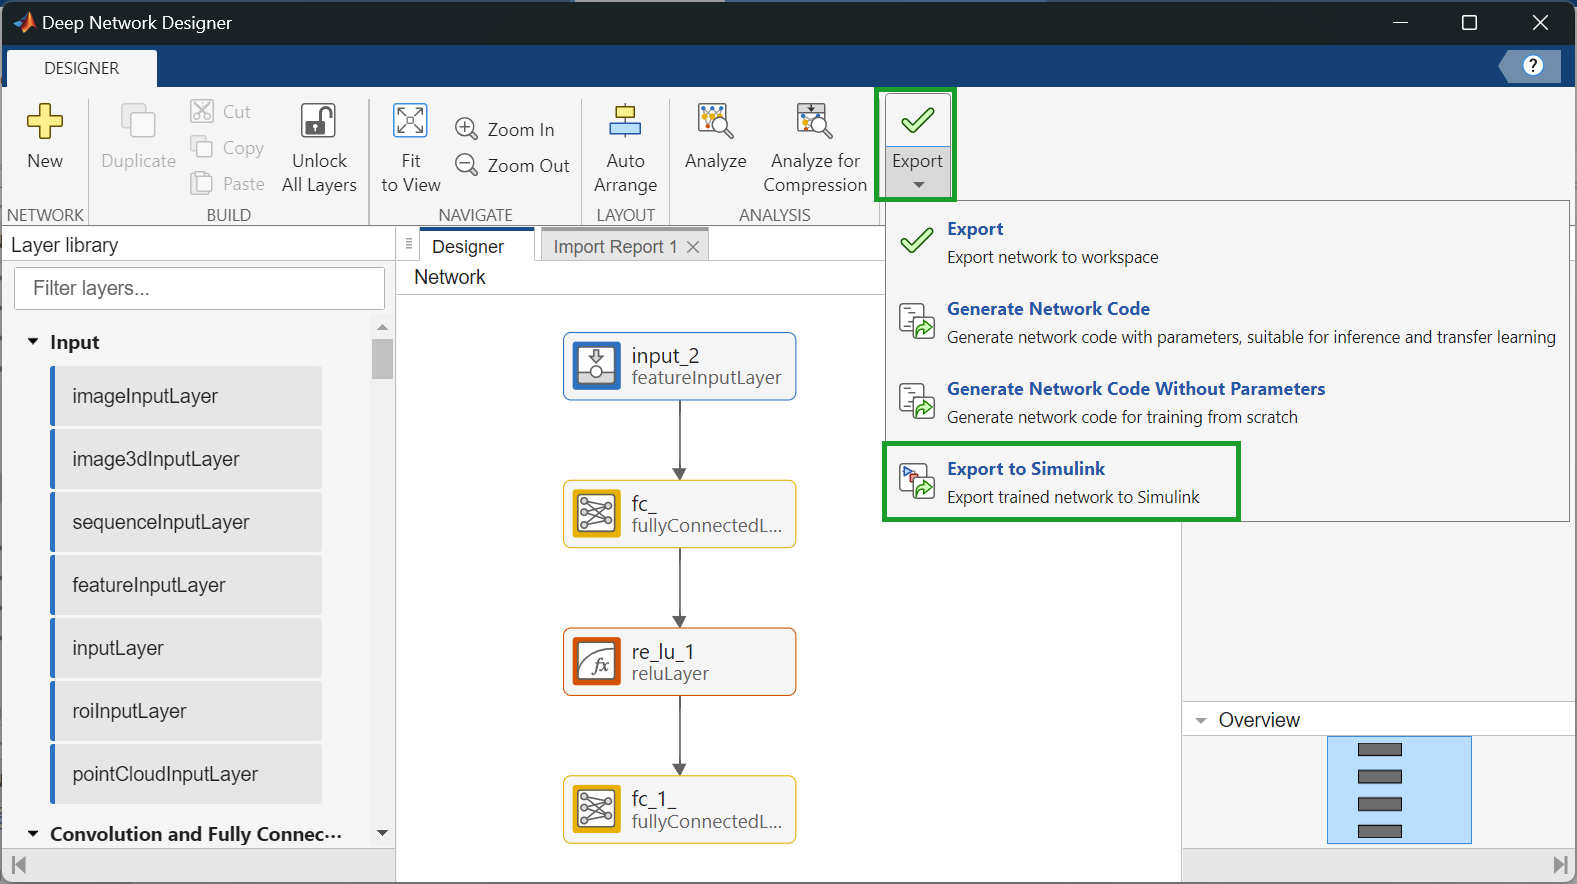

The app has two types of Simulink export:

- Export to a single network block, for example, a Predict block

- Export to multiple layer blocks

For small networks with all layers supported as layer blocks, exporting to layer blocks is recommended. For large networks or networks with layers not supported as layer blocks, exporting to a single network block is recommended. You can experiment with both options. For this workshop, we will use a single network block for all our exercise

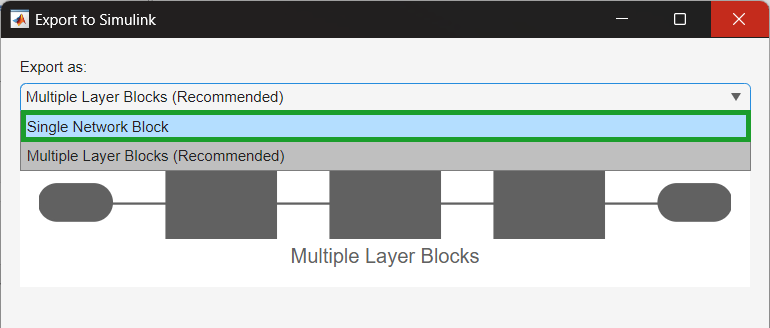

Keep the default location and click Export.

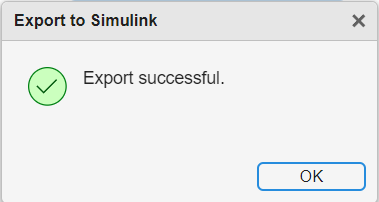

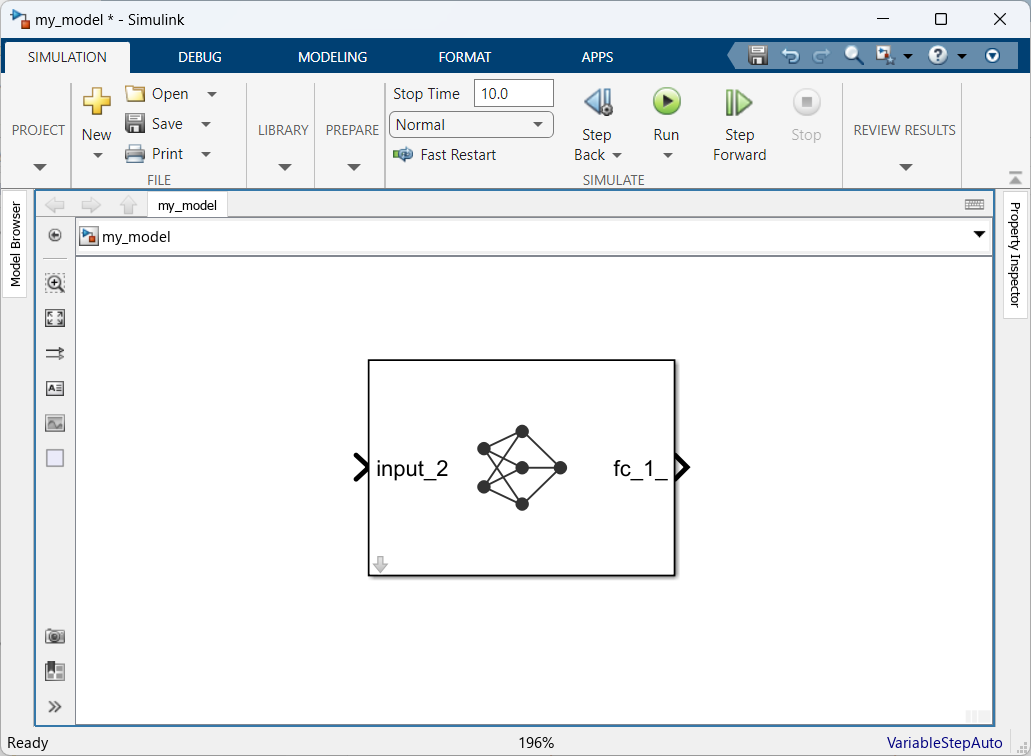

### 5.Specify the input format in the Predict block

Note the AI model is automatically saved as a MAT file along with the SImulink model .

**To Do:** As we did in the previous exercise, double click on the **Predict Block** to open the **Block Parameters** menu. Specify the **Input data format** as "CB" - this means the input data is formatted as *c*-by-*n* array, where *c* is the number of features, and *n* is the number of observations. 

### **6.Generate the Inputs for Simulink**

In Simulink, there are several ways how you can import data: "From Workspace" block, "Inport" block, "From File" block and others. We are going to use "From Workspace" blocks. We need to generate the inputs for Simulink in the correct format and we can use the left-out test data set.

dataFolder = helper.getDataFolder();
testFile = fullfile(dataFolder,"Test","01_TEST_LGHG2@n10degC_Norm_(05_Inputs).mat");
S = load(testFile);
steps = size(S.X,2);
t = (0:(steps-1))';
X_in = timeseries(single(S.X'), t);
true_SOC = timeseries(single(S.Y'), t);

### 7.Configure Model Parameters for Simulations

Open the **Configuration Parameters** dialog (or Ctrl+E) and set **Stop time **to the workspace variable named "steps" (which is the total number of simulation steps; this variable will be generated in a later section), and set the solver to "Fixed-step" and "Discrete" with a fundamental step size of 1:

### 8.Connect the Model

Add two "From Workspace" blocks with "X_in" and "true_SOC" for the data variables, respectively. Connect the "X_in" input to the "Predict" block. Connect the "true_SOC" input to a "Scope" block in the following way:

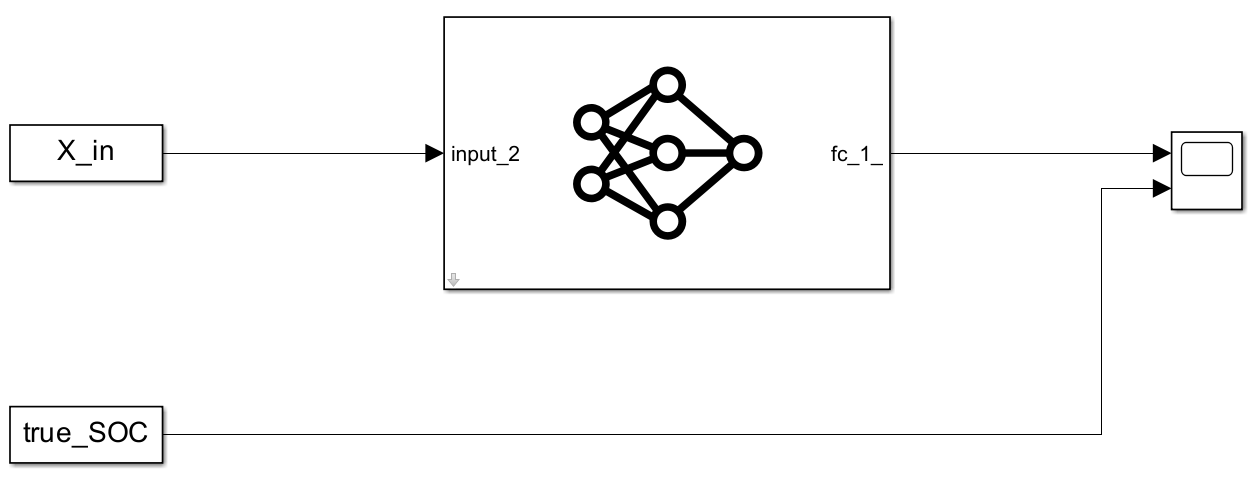

### 9.Run the Simulink Model

Now we can simulate the model by clicking the "Run" button and double-click on the "Scope" block to inspect simulation results:

(You may check `exampleModel_TF_import.slx` if you run into any issues)

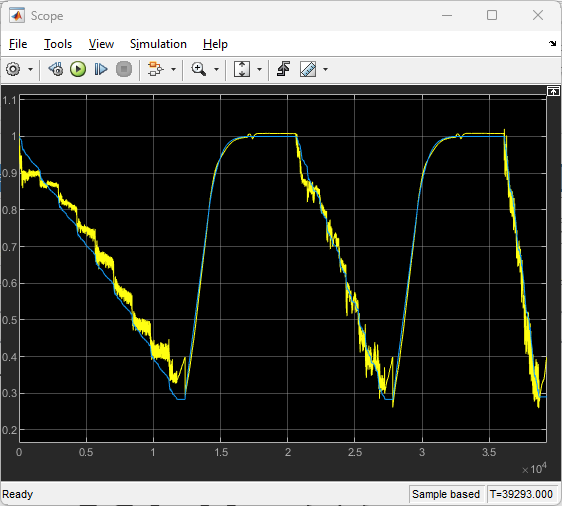

## Part 3: Generate Code from Deep Learning Models

### 1.Load Previously Trained LSTM Network

clear
origFileName = 'DLmodel_ref_stackedLSTM.mat';
projectedFileName = 'DLmodel_ref_stackedLSTM_Projected.mat';
load(origFileName);
recurrentNet.Layers
analyzeNetwork(recurrentNet)

Note that the original LSTM network has 463.4k learnables. By default, in MATLAB, DL network learnables are stored in single-precision, floating-point format (fp32). At 4 bytes (32 bits) per learnable, this translates to a total learnables size of **~1.85 MB**. 

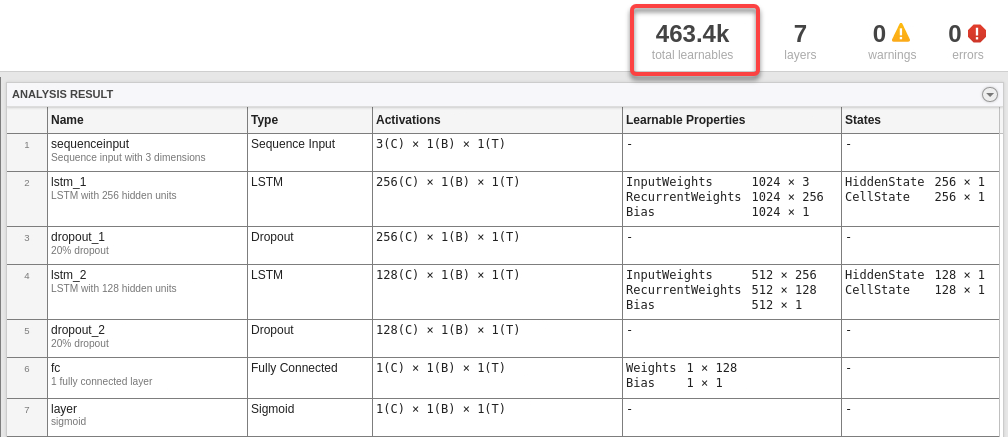

### 2.Data Preparation

dataFolder = helper.getDataFolder;
chunkSize = 500;
numFeatures = 3;

trainingFile = fullfile(dataFolder,"Train","TRAIN_LGHG2@n10degC_to_25degC_Norm_5Inputs.mat");
[XTrain,YTrain] = helper.setupDataLSTM(trainingFile,chunkSize,numFeatures);
validationFile = fullfile(dataFolder,"Validation", "01_TEST_LGHG2@n10degC_Norm_(05_Inputs).mat");
[XVal,YVal] = helper.setupDataLSTM(validationFile,chunkSize,numFeatures);

for i = 1:numel(XTrain)
    XTrain{i} = XTrain{i}.';
    YTrain{i} = YTrain{i}.';
end
for i = 1:numel(XVal)
    XVal{i} = XVal{i}.';
    YVal{i} = YVal{i}.';
end

### 3.Model Compression - Projection

**Understanding network compression with projection**

To compress a neural network, MATLAB uses a technique that involves projecting the network's layers into smaller parameter subspaces, thereby reducing the memory footprint of the model. This is done by introducing projector matrices that transform the learnable parameters into a lower-dimensional space without significantly compromising prediction accuracy. A projected deep neural network can also exhibit faster forward passes (inference) or deployed to embedded hardware using library-free C or C++ code generation, making projection a powerful technique for both reducing memory requirements and boosting throughput. To learn more about the algorithm based on principal component analysis (PCA) underlying network projection, refer to [this page](https://www.mathworks.com/company/newsletters/articles/compressing-neural-networks-using-network-projection.html).

As of R2024a, the following network layers support compression with projection:

- `convolution2dLayer`

- `fullyConnectedLayer`

- `lstmLayer`

- `gruLayer`

**Explore Compression Levels**

A trade-off exists between the amount of compression we apply to the network and its accuracy. In general, reducing the number of learnable parameters in a pretrained network will reduce its accuracy. Let's experiment by compressing the network with projection by a range of increasing amounts. To do this, let's iterate over 20 values of the `ExplainedVarianceGoal` in put argument to the `compressNetworkUsingProjection `function and plot the results. Then, we can decide on a worthwhile trade-off point between network size and accuracy.

The explained variance of a network details how well the space of network activations can capture the underlying features of the data. To explore different amounts of compression, you can iterate over different values of the ExplainedVarianceGoal option of the compressNetworkUsingProjection function and compare the results.

mbSize = 48;
mbq = minibatchqueue(...
    arrayDatastore(XTrain(1:10:end-1),OutputType="same",ReadSize=mbSize),...
    MiniBatchSize=mbSize,...
    MiniBatchFormat="TCB",...
    MiniBatchFcn=@(X) cat(3,X{:}));

npca = neuronPCA(recurrentNet, mbq); % Create Neuron Principal Component Analysis (PCA) object
numValues = 20;
explainedVarGoal = 1 - logspace(-3,0,numValues);
explainedVariance = zeros(1,numValues);
learnablesReduction = zeros(1,numValues);
accuracy = zeros(1,numValues);

S = load(validationFile);
XTest = S.X(1:numFeatures,:);
YTest = S.Y';

for i = 1:numel(explainedVarGoal)
    varianceGoal = explainedVarGoal(i);

    [dlnetProjected,info] = compressNetworkUsingProjection(recurrentNet, npca, ...
        ExplainedVarianceGoal=varianceGoal, ...
        VerbosityLevel="off");

    explainedVariance(i) = info.ExplainedVariance;
    learnablesReduction(i) = info.LearnablesReduction;
    
    YPredProjected = predict(dlnetProjected, dlarray(XTest,"CTB"));
    YPredProjected = extractdata(YPredProjected(:));
    accuracy(i) = sqrt(mean((YTest - YPredProjected).^2));
end

Visualize the effect of the different settings of the explained variance goal.

figure
tiledlayout("flow")
nexttile
plot(learnablesReduction,accuracy,'+-')
hold on
plot(0.93, 0.128, 'r*')
xlabel("Learnables Reduction")
ylabel("RMSE")
title("Effect of Explained Variance Goal")

nexttile
plot(learnablesReduction,explainedVariance,'+-')
ylim([0 inf])
ylabel("Explained Variance")
xlabel("Learnables Reduction")

The graph shows that an increase in learnable reduction has a corresponding increase in RMSE (decreace in accuracy). A learnable reduction value of around **93%** shows a good compromise between explained variance and RMSE.

### 4.Compress stacked-LSTM via Projection of Layers

dlnetProjected = compressNetworkUsingProjection(recurrentNet, mbq, LearnablesReductionGoal = 0.93); % project network with 93% learnables reduction value
analyzeNetwork(dlnetProjected)

The new, projected network has 32.3k learnables. Still stored in `fp32`, the size now amounts to **~0.13 MB**. 

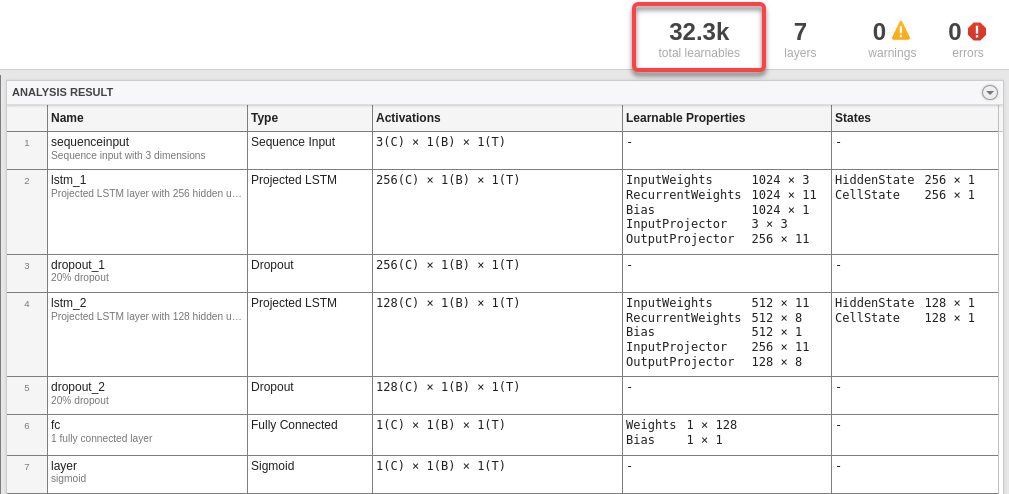

### 5.Fine-tune Compressed Stacked-LSTM Network

Starting with a pretrained network, the projected network equivalent can be directly computed as demonstrated above. Although a high degree of data covariance is retained, the network may need fine-tuning as accuracy can drop following the compression. This could be a result of higher order nonlinear relations between neurons in the network needing to readjust given the linear transformation or a compounding effect if many layers are projected at once. The projected model provides a good initialization for fine-tuning by further retraining. The fine-tune retraining typically takes far fewer epochs for the accuracy to plateau and can largely recover, in many cases, the accuracy of the original network.

doTraining = false; % Set to true if you would like to run fine-tuning, otherwise, the script will load a fine-tuned model from file below

if doTraining  

    options = trainingOptions("adam", ...
        MaxEpochs = 300,...
        ExecutionEnvironment = "auto", ...
        InitialLearnRate = 1e-2, ...
        LearnRateSchedule = "piecewise",...
        LearnRateDropPeriod = 120,...
        LearnRateDropFactor = 0.1,...
        GradientThreshold = 1,...
        Shuffle = "every-epoch",...
        Verbose = false,...
        ValidationFrequency = 10, ...
        MiniBatchSize = 64, ...
        Plots = "training-progress", ...
        ValidationData = {XVal,YVal});
    
    recurrentNetProjected = trainnet(XTrain,YTrain,dlnetProjected,"mse",options);
else
    load(projectedFileName);
end

testFile = fullfile(dataFolder,"Test","01_TEST_LGHG2@n10degC_Norm_(05_Inputs).mat");
S = load(testFile);

XTest = S.X(1:numFeatures,:)';
YTest = S.Y;

YPredProjected = predict(recurrentNetProjected, XTest);

[RMSEProjectedNN,residualsProjectedNN] = rmse(YTest,YPredProjected);

figure
plot(residualsProjectedNN);
title("Residuals","RMSE: " + RMSEProjectedNN)
xlabel("Sample")
ylabel("Y-Y_{pred}")
% Calculate network accuracy
1 - RMSEProjectedNN

### 6. Generate code for AI and Compressed AI model

1.Open the model:

open_system("SOC_model_Code_Gen");

Open the **Configuration Parameters** dialog (or Ctrl+E) and set **Simulation Target **to **C**

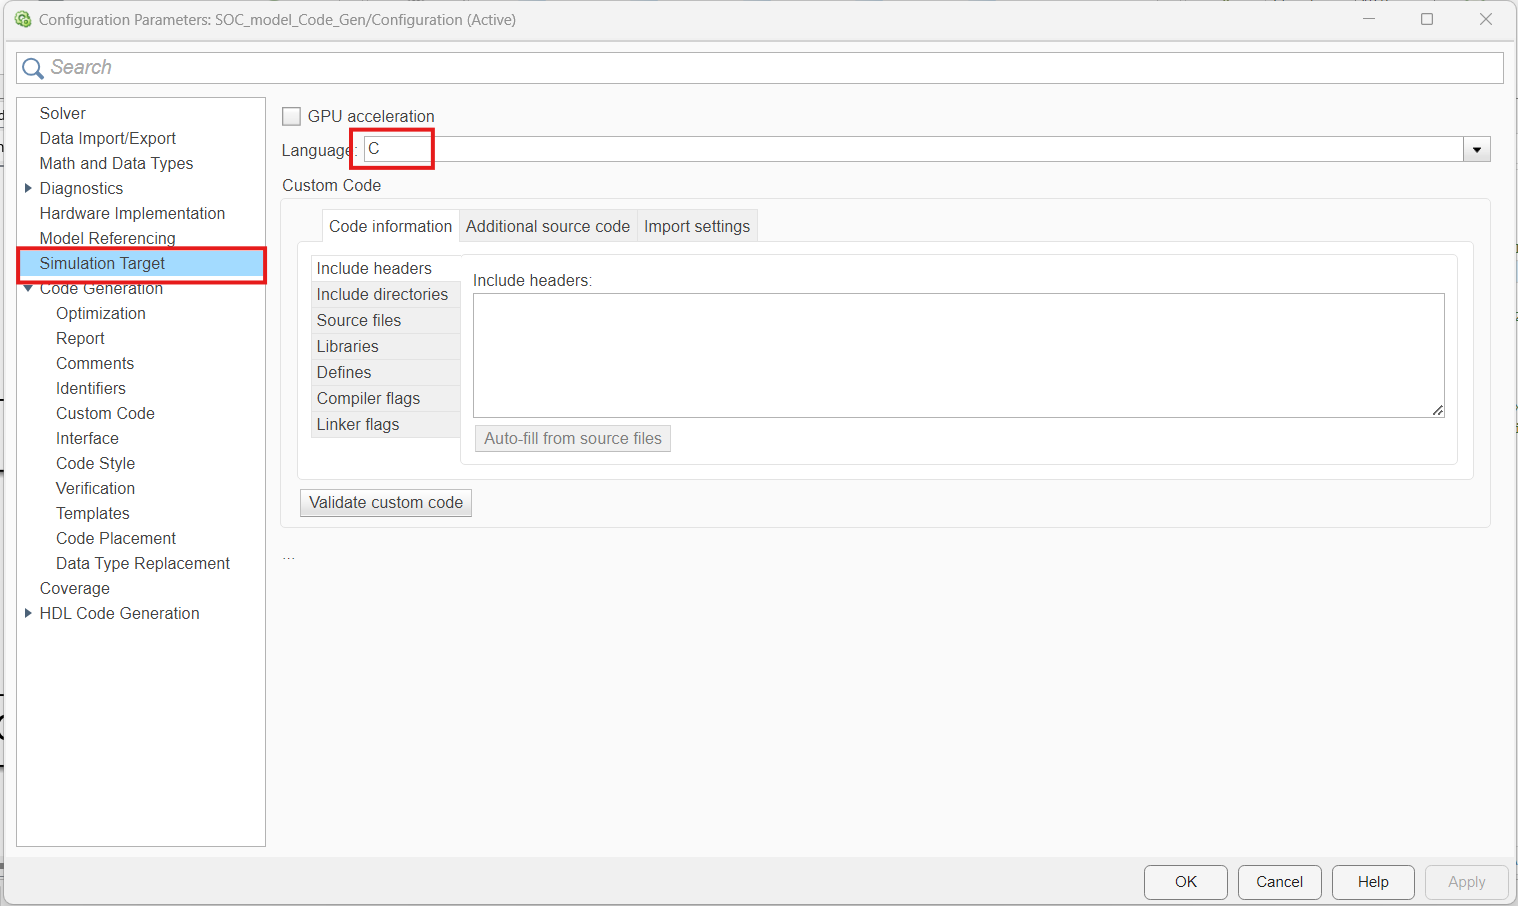

Uncheck the "**Enable portable word sizes**"

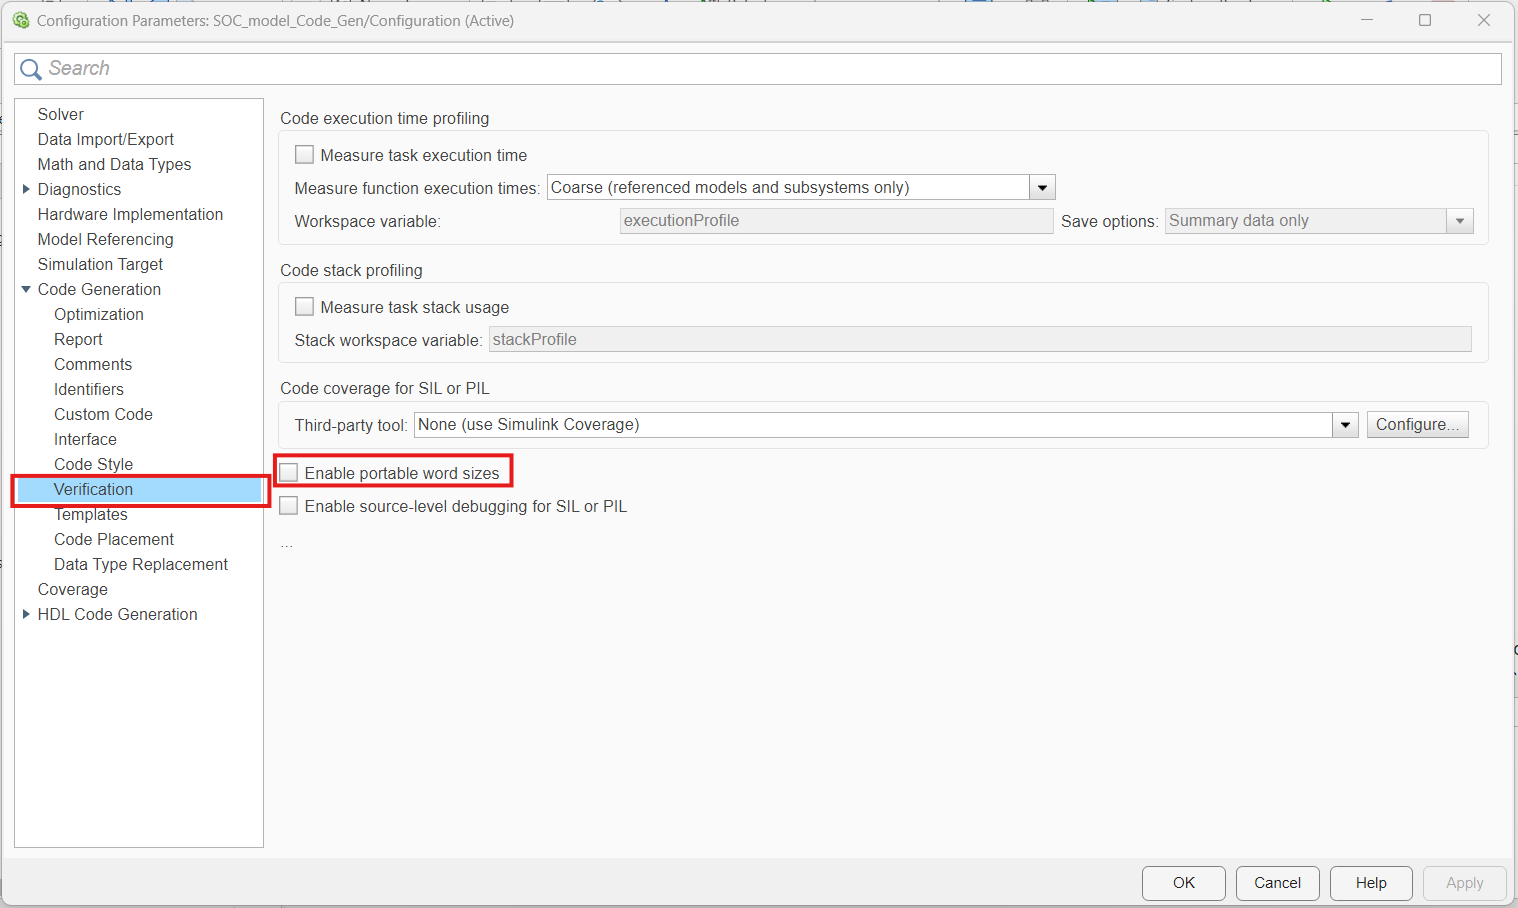

2.To generate code from the **AI subsystem** and inspect the **Static Code Metrics** Report:

- Right-click the **AI Subsystem**

- Select **C/C++ Code** > **Build This Subsystem**.

Optional: here are the configuration steps that have been set up for you for your reference. These configurations have been saved with the model.

- Click into the **AI** **subsystem** and apply the same settings for both LSTM and LSTM Projected subsystems. On the **Subsystem Block** pane, under **Component**, click **Atomic Subsystem**. Right-click the subsystem, and select **Block Parameters** **(subsystem)**. In the **Code Generation** tab, set **Function Packaging** to **Nonreusable function**.

- Open the Configuration Parameters dialog box. In the Simulink Editor, on the **Modeling** tab, click **Model Settings**.

- On the **Code Generation** pane, under **Target selection**, specify the system target file as `ert.tlc`.

- Under **Build process**, uncheck **Generate code only**

- On the **Code Generation **> **Optimization** pane, set **Leverage target hardware instruction set extensions **to **None**

3.Inspect Generated Code

Click "Open Report" on the "C Code" tab on the Simulink Toolstrip.

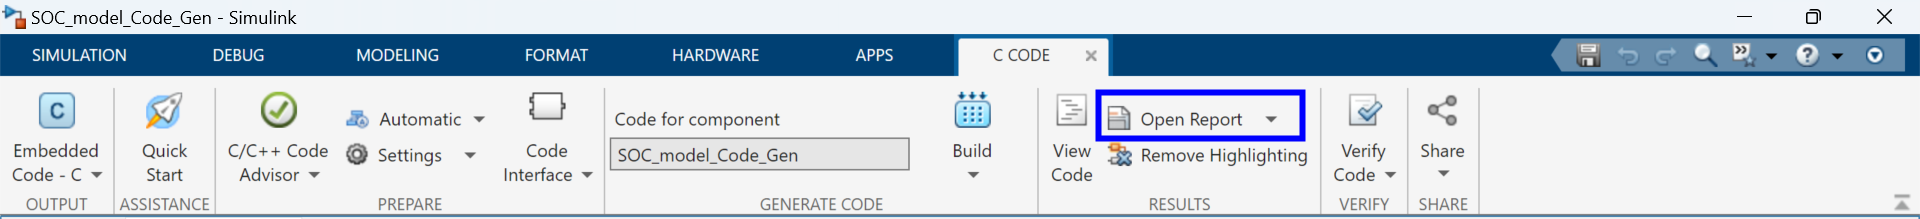

After the **Code Generation Report** window opens, in the "Code" section on the left-hand side panel, click through the "Model files" to inspect the content of the code.

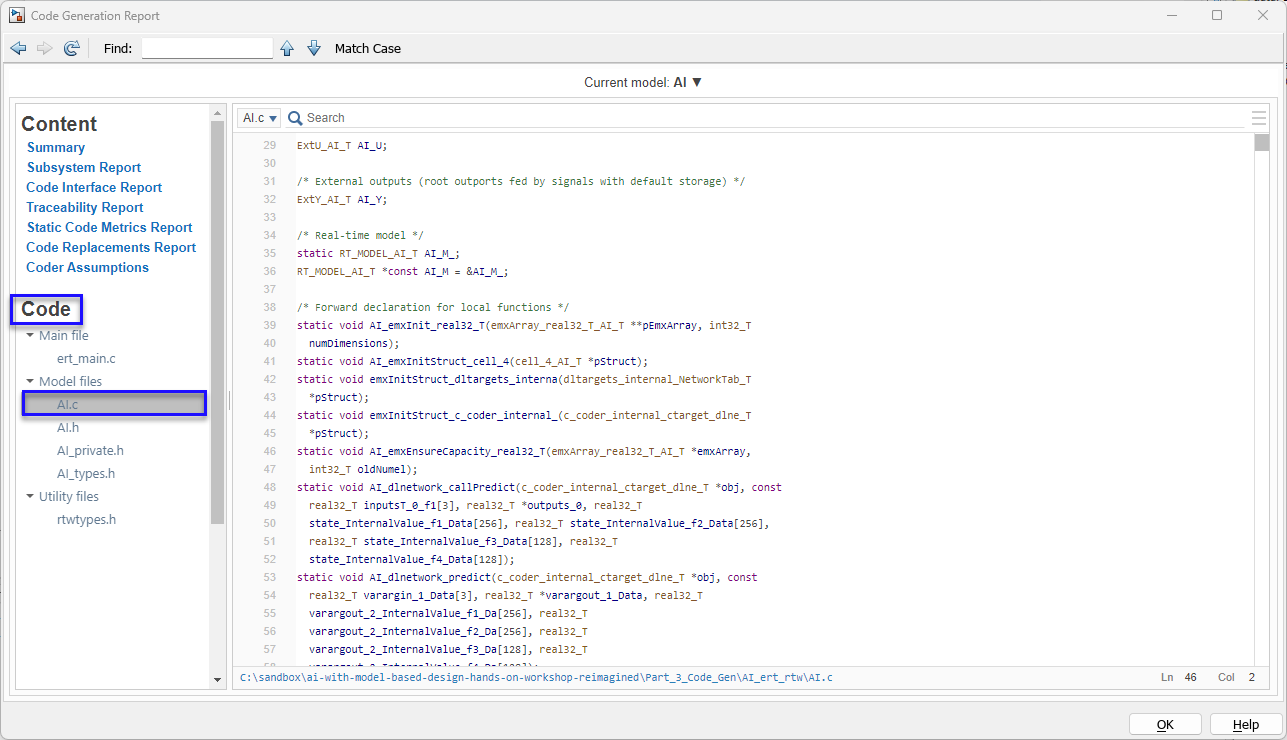

## References

[1] Kollmeyer, Phillip, Carlos Vidal, Mina Naguib, and Michael Skells. “LG 18650HG2 Li-Ion Battery Data and Example Deep Neural Network XEV SOC Estimator Script.” Mendeley, March 5, 2020. [https://doi.org/10.17632/CP3473X7XV.3.](https://doi.org/10.17632/CP3473X7XV.3.)

Root mean squared error helper function

function [rmseValue,residuals] = rmse(y,t)
    residuals = y(:)-t(:);
    rmseValue = sqrt(mean(residuals.^2));
end